Function

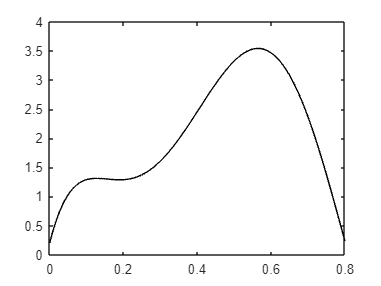

f=@(x) 400.*x.^5 - 900.*x.^4 + 675.*x.^3 - 200.*x.^2 + 25.*x + 0.2;

xx = linspace(0, 0.8);
yy = f(xx);
plot(xx,yy,'k-')

To integrate function from 0 to 0.8

a = 0;
b = 0.8;

p = [400 -900 675 -200 25 0.2];
q = polyint(p);

Itrue = diff(polyval(q, [a b]))

Itrue = 1.6405

Compute using composite trapezoidal rule

ns = 200;

for k = 1:ns
    I_trap(k) = trap(f,a,b,k);
    err(k) = ( (Itrue - I_trap(k) ) / Itrue) * 100;
end

[(1:ns)' I_trap' err']

ans =     1.0000    0.1728   89.4668
    2.0000    1.0688   34.8505
    3.0000    1.3696   16.5166
    4.0000    1.4848    9.4928
    5.0000    1.5399    6.1353
    6.0000    1.5703    4.2833
    7.0000    1.5887    3.1569
    8.0000    1.6008    2.4220
    9.0000    1.6091    1.9164
   10.0000    1.6150    1.5538


Compute using Romberg integration

[I_romberg, ea, iter] = romberg(f,a,b)

I_romberg = 1.6405

ea = 0

iter = 3

Compute using Gauss-Legendre Formulas

a1 = (b+a)/2;
a2 = (b-a)/2;

% x = a1 + a2 * xd
% dx = a2 + dxd

f2=@(xd) (400.*(a1 + a2 * xd).^5 - 900.*(a1 + a2 * xd).^4 + 675.*(a1 + a2 * xd).^3 - 200.*(a1 + a2 * xd).^2 + 25.*(a1 + a2 * xd) + 0.2)*a2;

I_2_points = f2(-1/sqrt(3)) + f2(1/sqrt(3))

I_2_points = 1.8226

I_3_points = (5/9) * f2(-sqrt(3/5)) + ((8/9)*f2(0)) + (5/9)*f2(sqrt(3/5))

I_3_points = 1.6405

I_4_points = ((18 - sqrt(30))/36) * f2( (-sqrt( 525+70*sqrt(30) ))/35 ) + ((18 + sqrt(30))/36) * f2( (-sqrt( 525-70*sqrt(30) ))/35 ) + ((18 + sqrt(30))/36) * f2( (sqrt( 525-70*sqrt(30) ))/35 ) + ((18 - sqrt(30))/36) * f2( (sqrt( 525+70*sqrt(30) ))/35 )

I_4_points = 1.6405

Compute using adaptive quadrature

I_quadadapt = quadadapt(f,a,b)

I_quadadapt = 1.6405

Compute using Matlab's integral function

I_integral = integral(f,a,b)

I_integral = 1.6405